%%%%%%%%%%%%%%
mode = 12;
%%%%%%%%%%%%%%


%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=60,nK=64,latitude=latExp);
toc

[z_g,G,F,h,mMax,N2,f] = quadraturePoints(mode);

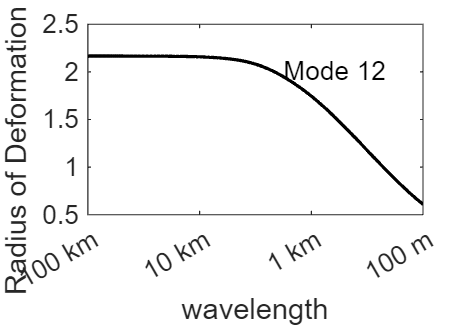

figure(2)

hMode=squeeze(igw.h(mode,:));
Lr = sqrt(igw.g*hMode)./igw.f0; %[m]
Lr = Lr/10^3; %[km]

plot(log10(igw.KRadialLog), Lr, 'k', 'LineWidth', 1.5);
xlim([min(log10(igw.KRadialLog)) max(log10(igw.KRadialLog))])
xticks(log10(2*pi./[1e5 1e4 1e3 1e2]))
xticklabels({'100 km','10 km', '1 km', '100 m'})
xlabel('wavelength')
ylabel('Radius of Deformation [km]')


annotation('textbox', [0.55, 0.75, 0.3, 0.1], ...
    'String', 'Mode 12', ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'top', ...
    'FontSize', 12, ...
    'EdgeColor', 'none'); 

set(gca, 'FontSize', 12)
% Save
% Definir tamanho da figura
set(gcf, 'Units', 'centimeters', 'Position', [5,0, 10, 7]);

% Salvar com tamanho e qualidade especificados
exportgraphics(gcf, ['Radius of Deformation [km] -MODE12', '.png'], ...
    'Resolution', 300);